# The solution of problem (e)

`odefcn`, a local function included at the end of the script, represents this system of equations as a function that accepts four input arguments: `t`, x.

Solve the ODE using `ode45,`tspan is the range of values of t, and x0 is the initial value. 

tspan2 = [0 0.1];
x0 = [0 0];
[t,x] = ode45(@(t,x) odefcn(t,x), tspan2, x0);

**Vertical acceleration chang to 0.5g**

Plot the results of vertical acceleration.

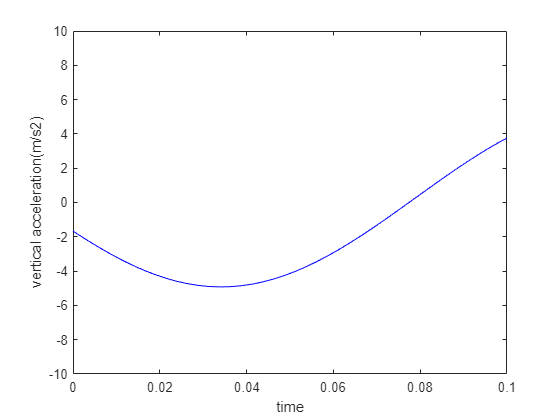

plot(t,(-0.2*x(:,2)-20*x(:,1)-1.666*cos(30/3.6/0.235*t)-4.7*sin(30/3.6/0.235*t)),'-b')
xlabel('time')
ylabel('vertical acceleration(m/s2)')
xlim([0.00 0.1])
ylim([-10 10])

min(-0.2*x(:,2)-20*x(:,1)-1.666*cos(30/3.6/0.235*t)-4.7*sin(30/3.6/0.235*t))% The maximal vertical accelerationadditional.

ans = -4.9218

**Different car velocities**

Plot the results of vertical acceleration, The method is the same as above, and only the speed parameters are changed to 20km/h and 40km/h.

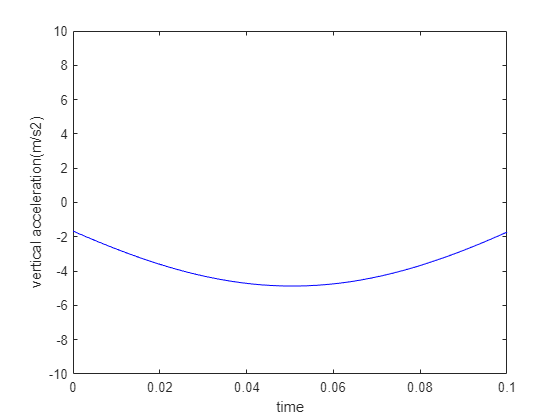

tspan1 = [0 0.1];
x0 = [0 0];
[t,x1] = ode45(@(t,x1) odefcn1(t,x1), tspan1, x0);
tspan2 = [0 0.1];
x0 = [0 0];
[t,x2] = ode45(@(t,x2) odefcn2(t,x2), tspan2, x0);
plot(t,(-0.2*x1(:,2)-20*x1(:,1)-1.666*cos(20/3.6/0.235*t)-4.7*sin(20/3.6/0.235*t)),'-b')
xlabel('time')
ylabel('vertical acceleration(m/s2)')
xlim([0.00 0.1])
ylim([-10 10])

min(-0.2*x1(:,2)-20*x1(:,1)-1.666*cos(20/3.6/0.235*t)-4.7*sin(20/3.6/0.235*t))

ans = -4.8725

 The acceleration decreases when the velocity is 20 km/h.

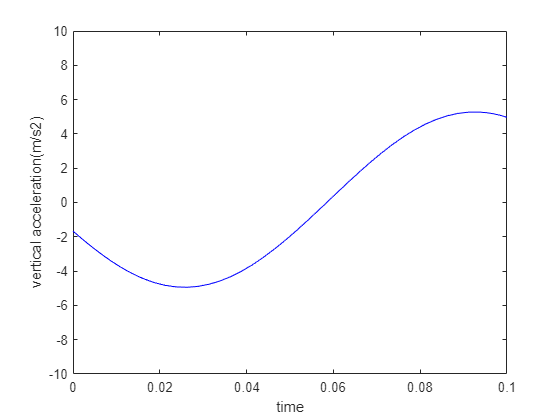

plot(t,(-0.2*x2(:,2)-20*x2(:,1)-1.666*cos(40/3.6/0.235*t)-4.7*sin(40/3.6/0.235*t)),'-b')
xlabel('time')
ylabel('vertical acceleration(m/s2)')
xlim([0.00 0.1])
ylim([-10 10])

min(-0.2*x2(:,2)-20*x2(:,1)-1.666*cos(40/3.6/0.235*t)-4.7*sin(40/3.6/0.235*t))

ans = -4.9424

The acceleration increases when the velocity is 40 km/h.

function dx = odefcn(t,x)
  dx = zeros(2,1);
  dx(1) = x(2);
  dx(2) = -0.2*x(2)-20*x(1)-1.666*cos(30/3.6/0.235*t)-4.7*sin(30/3.6/0.235*t);
end

function dx1 = odefcn1(t,x1)
  dx1 = zeros(2,1);
  dx1(1) = x1(2);
  dx1(2) = -0.2*x1(2)-20*x1(1)-1.666*cos(30/3.6/0.235*t)-4.7*sin(20/3.6/0.235*t);
end

function dx2 = odefcn2(t,x2)
  dx2 = zeros(2,1);
  dx2(1) = x2(2);
  dx2(2) = -0.2*x2(2)-20*x2(1)-1.666*cos(30/3.6/0.235*t)-4.7*sin(40/3.6/0.235*t);
end